n = 54;
meanTEQ = 45;
sdTEQ = 7;
empathy = round(min(max(meanTEQ + sdTEQ * randn (54,1),0),64))

empathy =     49
    49
    30
    36
    35
    48
    55
    43
    51
    49
    38
    48
    40
    56
    45


meanBrainActivity = 100;
sdBrainActivity = 10;
brain_activity = round(meanBrainActivity + sdBrainActivity * randn(54,1))

brain_activity =    103
    98
   102
   104
    94
   103
   106
   101
   117
    94
    93
    83
   109
   109
    99


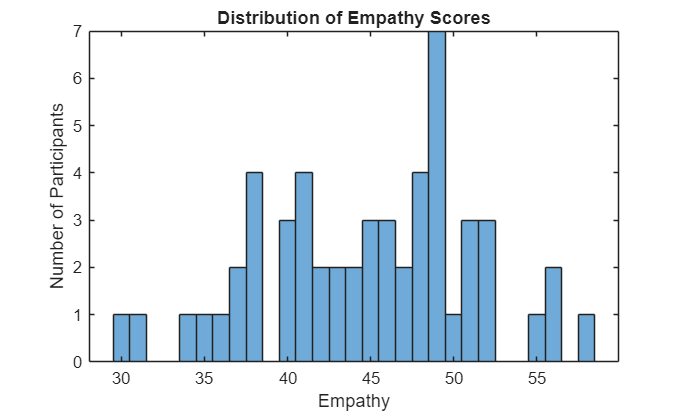


histogram(empathy)
xlabel('Empathy')
ylabel('Number of Participants')
title ('Distribution of Empathy Scores')

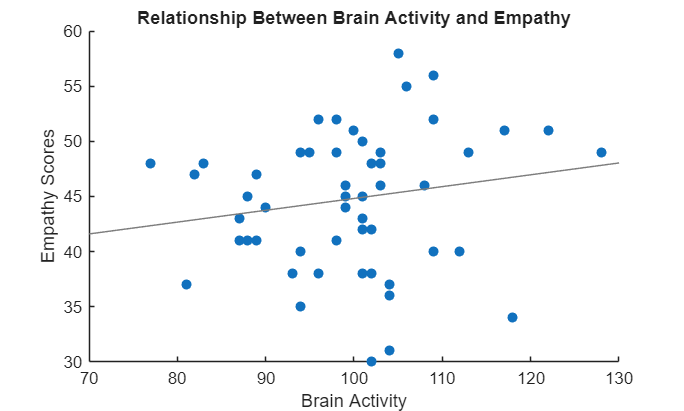


scatter(brain_activity, empathy, "filled")
xlabel('Brain Activity')
ylabel('Empathy Scores')
title('Relationship Between Brain Activity and Empathy')
lsline


model = fitlm(brain_activity, empathy)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     34.098       8.6459    3.9438    0.00024112
    x1             0.10725     0.086089    1.2458       0.21843


Number of observations: 54, Error degrees of freedom: 52
Root Mean Squared Error: 6.35
R-squared: 0.029,  Adjusted R-Squared: 0.0103
F-statistic vs. constant model: 1.55, p-value = 0.218

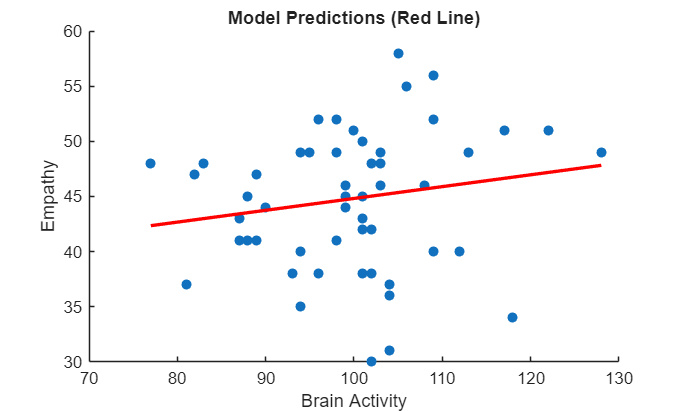


predicted_empathy = predict(model, brain_activity);

scatter(brain_activity, empathy, "filled")
hold on
plot(brain_activity, predicted_empathy, 'r', 'LineWidth', 2)
hold off
xlabel('Brain Activity')
ylabel('Empathy')
title('Model Predictions (Red Line)')